# Optimization and Data Analytics HW5

## An Introduction to Optimization sec. 20

## Exercise 20.2

Find local extremizers for the following optimization problems:

## a)

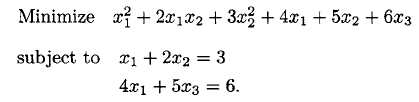

This optimization problem may be represented by:

**minimize** $f\left(x\right)$

**subject** **to**  $h\left(x\right)=0$

**Where** $f\left(\mathit{\mathbf{x}}\right)=x_1^2 +2x_1 x_2 +3x_2^2 +4x_1 +5x_2 +6x_3$ and $h\left(\mathit{\mathbf{x}}\right)=\left\lbrack \begin{array}{c}
x_1 +2x_2 -3\\
4x_1 +5x_3 -6
\end{array}\right\rbrack$

syms x1 x2 x3
x = [x1; x2; x3];
f = @(x1,x2,x3) x1^2+2*x1*x2+3*x2^2+4*x1+5*x2+6*x3;
h1 = @(x1,x2) x1+2*x2-3;
h2 = @(x1,x3) 4*x1+5*x3-6;
h = {h1; h2};

Lagrange's theorem provides a first-order necessary condition for a point to be a local minimizer. This condition is called the *Langrangian* *condition*, and may be expressed by applying the FONC of *unconstrained optimization *to the Langrangian function *L*

$L\left(x,\lambda \right)=f\left(x\right)+\lambda^T h\left(x\right)$ where $\lambda =\left\lbrack \begin{array}{c}
\lambda_1 \\
\lambda_2 
\end{array}\right\rbrack$

The Langrangian condition is then:


$$\mathit{DL}\left(x,\lambda \right)=0^T$$


syms lambda1 lambda2
lambda = [lambda1; lambda2];
l = f(x1,x2,x3)+lambda'*h

$$l = 4\,x_{1}+5\,x_{2}+6\,x_{3}+\bar{\lambda_{2}}\,\left(4\,x_{1}+5\,x_{3}-6\right)+2\,x_{1}\,x_{2}+{x_{1}}^{2}+3\,{x_{2}}^{2}+\bar{\lambda_{1}}\,\left(x_{1}+2\,x_{2}-3\right)$$

Critical points satisfying the langrangian condition are then found by solving the equations:


$${\text{D}}_{x_1 } \text{L}\left(x,\lambda \right)=2x_1 +2x_2 +\lambda_1 +{4\lambda }_2 +4=0^T$$



$$D_{x_2 } L\left(x,\lambda \right)=2x_1 +6x_2 +2\lambda_1 +5=0^T$$



$$D_{x_3 } L\left(x,\lambda \right)=5\lambda_2 +6=0^T$$



$$D_{\lambda_1 } L\left(x,\lambda \right)=x_1 +2x_2 -3=0^T$$



$$D_{\lambda_2 } L\left(x,\lambda \right)=4x_1 +5x_3 -6=0^T$$


diff(l,x1)

$$ans = 2\,x_{1}+2\,x_{2}+\bar{\lambda_{1}}+4\,\bar{\lambda_{2}}+4$$

diff(l,x2)

$$ans = 2\,x_{1}+6\,x_{2}+2\,\bar{\lambda_{1}}+5$$

diff(l,x3)

$$ans = 5\,\bar{\lambda_{2}}+6$$

diff(l,lambda1)

$$ans = x_{1}+2\,x_{2}-3$$

diff(l,lambda2)

$$ans = 4\,x_{1}+5\,x_{3}-6$$

These equations may be solved by forming the linear system and solving through matrix reduction:

A = [2 2 0 1 4 -4;
    2 6 0 2 0 -5;
    0 0 0 0 5 -6;
    1 2 0 0 0 3;
    4 0 5 0 0 6]

A =      2     2     0     1     4    -4
     2     6     0     2     0    -5
     0     0     0     0     5    -6
     1     2     0     0     0     3
     4     0     5     0     0     6


A_ = rref(A)

A_ =     1.0000         0         0         0         0    3.2000
         0    1.0000         0         0         0   -0.1000
         0         0    1.0000         0         0   -1.3600
         0         0         0    1.0000         0   -5.4000
         0         0         0         0    1.0000   -1.2000


x_sol = [A_(1,6) A_(2,6) A_(3,6)]

x_sol =     3.2000   -0.1000   -1.3600


lambda_sol = [A_(4,6) A_(5,6)]

lambda_sol =    -5.4000   -1.2000


The solution satisfying the Langrangian condition is therefore:


$$x=\left\lbrack \begin{array}{c}
3\ldotp 2\\
-0\ldotp 1\\
-1\ldotp 36
\end{array}\right\rbrack ,\text{  }\lambda =\left\lbrack \begin{array}{c}
-5\ldotp 4\\
-1\ldotp 2
\end{array}\right\rbrack$$


The Langrangian condition is necessary but not sufficient to say that a point ${\mathit{\mathbf{x}}}^\ast $ is a minimizer. In order to say that a point is a minimizer the SOSC is evaluated.

Evaluating the solution in terms of the SOSC:


$$y^T \ast L\left(x^\ast  ,\lambda^\ast  \right)\ast y>0$$


Where:


$$L\left(x,\lambda \right)=F\left(x\right)+\left\lbrack \lambda H\left(x\right)\right\rbrack =D^2 f\left(x+\right)+\left\lbrack \lambda D^2 h\left(x\right)\right\rbrack$$


The Hessian of *f* is given by:


$$D^2 f\left(x\right)=\left\lbrack \begin{array}{ccc}
\frac{\partial^2 }{\partial x_1^2 }f\left(x\right) & \frac{\partial^2 }{{\partial x}_1 x_2 }f\left(x\right) & \frac{\partial^2 }{\partial x_1 x_3 }f\left(x\right)\\
\frac{\partial^2 }{{\partial x}_2 x_1 }f\left(x\right) & \frac{\partial^2 }{\partial x_2^2 }f\left(x\right) & \frac{\partial^2 }{\partial x_2 x_3 }f\left(x\right)\\
\frac{\partial^2 }{\partial x_3 x_1 }f\left(x\right) & \frac{\partial^2 }{\partial x_3 x_2 }f\left(x\right) & \frac{\partial^2 }{\partial x_3^2 }f\left(x\right)\partial 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
2 & 2 & 0\\
2 & 6 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$$


D2f = [diff(f,x1,x1) diff(f,x1,x2) diff(f,x1,x3);
       diff(f,x2,x1) diff(f,x2,x2) diff(f,x2,x3);
       diff(f,x3,x1) diff(f,x3,x2) diff(f,x3,x3)]

$$D2f = \left(\begin{array}{ccc} 2 & 2 & 0\\ 2 & 6 & 0\\ 0 & 0 & 0 \end{array}\right)$$

The expression $\lambda D^2 h\left(x\right)$ is given by:


$$\lambda D^2 h\left(x\right)=\lambda \left\lbrack \begin{array}{ccc}
\frac{\partial^2 }{\partial x_1^2 }h\left(x\right) & \frac{\partial^2 }{{\partial x}_1 x_2 }h\left(x\right) & \frac{\partial^2 }{\partial x_1 x_3 }h\left(x\right)\\
\frac{\partial^2 }{{\partial x}_2 x_1 }h\left(x\right) & \frac{\partial^2 }{\partial x_2^2 }h\left(x\right) & \frac{\partial^2 }{\partial x_2 x_3 }h\left(x\right)\\
\frac{\partial^2 }{\partial x_3 x_1 }h\left(x\right) & \frac{\partial^2 }{\partial x_3 x_2 }h\left(x\right) & \frac{\partial^2 }{\partial x_3^2 }h\left(x\right)\partial 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$$


lambda_D2h = [lambda'*diff(h,x1,x1) lambda'*diff(h,x1,x2) lambda'*diff(h,x1,x3);
              lambda'*diff(h,x2,x1) lambda'*diff(h,x2,x2) lambda'*diff(h,x2,x3);
              lambda'*diff(h,x3,x1) lambda'*diff(h,x3,x2) lambda'*diff(h,x3,x3)]

$$lambda\_D2h = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$


$$L=D^2 f\left(x+\right)+\left\lbrack \lambda D^2 h\left(x\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
2 & 2 & 0\\
2 & 6 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$$


L = D2f+lambda_D2h

$$L = \left(\begin{array}{ccc} 2 & 2 & 0\\ 2 & 6 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Determining an expression for the tangent plane:


$$T\left(x\right)=\left\lbrace \mathrm{Dh}\left(x\right)\ast y=0\right\rbrace$$


Where


$$\mathrm{Dh}\left(x\right)=\left\lbrack \begin{array}{ccc}
\frac{\partial }{\partial x_1 }h_1 \left(x\right) & \frac{\partial }{\partial x_2 }h_2 \left(x\right) & \frac{\partial }{\partial x_1 }h_3 \left(x\right)\\
\frac{\partial }{\partial x_1 }h_1 \left(x\right) & \frac{\partial }{\partial x_1 }h_2 \left(x\right) & \frac{\partial }{\partial x_1 }h_3 \left(x\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 2 & 0\\
4 & 0 & 5
\end{array}\right\rbrack$$


Dh = [diff(h1,x1) diff(h1,x2) diff(h1,x3);
      diff(h2,x1) diff(h2,x2) diff(h2,x3)]

$$Dh = \left(\begin{array}{ccc} 1 & 2 & 0\\ 4 & 0 & 5 \end{array}\right)$$

Solving with regards to **y **using the matrix system:


$$\left\lbrack \begin{array}{ccc}
1 & 2 & 0\\
4 & 0 & 5
\end{array}\right\rbrack \ast \left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
y_3 
\end{array}\right\rbrack =0\longrightarrow \left\lbrack \begin{array}{cccc}
1 & 2 & 0 & 0\\
4 & 0 & 5 & 0
\end{array}\right\rbrack \sim \left\lbrack \begin{array}{cccc}
1 & 0 & \frac{5}{4} & 0\\
0 & 1 & -\frac{5}{8} & 0
\end{array}\right\rbrack$$


The solution is then:

$y_1 =-\frac{5}{4},\text{  }y_2 =\frac{5}{8}$ and $y_3$ is *free variable*.

syms y1 y2 y3
[y1, y2] = solve(y1+2*y2==0,4*y1+5*y3==0)

$$y1 = -\frac{5\,y_{3}}{4}$$

$$y2 = \frac{5\,y_{3}}{8}$$

rref([1 2 0 0;
    4 0 5 0])

ans =     1.0000         0    1.2500         0
         0    1.0000   -0.6250         0


The tangent plane is then defined through the variable *a*:


$$T\left(x\right)=\left\lbrace a\left\lbrack \begin{array}{c}
-\frac{5}{4}\\
\frac{5}{8}\\
1
\end{array}\right\rbrack :a\in R\right\rbrace$$


Evaluating the SOSC,$y^T L\left(x,\lambda \right)y>0$, by letting:


$$y=a\ast \left\lbrack \begin{array}{c}
-\frac{5}{4}\\
\frac{5}{8}\\
1
\end{array}\right\rbrack$$


Then


$$y^T L\left(x,\lambda \right)y=\frac{75}{32}a^2 >0$$


syms a
y = a*[-5/4; 5/8; 1];
simplify(y'*L*y)

$$ans = \frac{75\,{\left|a\right|}^{2}}{32}$$

This is positive definite, which satisfies the SOSC and $x^\ast $ is therefore a strict **local minimizer**

## b)

Find local extremizers for the following optimization problems:

This optimization problem may be represented by:

**maximize** $f\left(x\right)$

**subject** **to**  $h\left(x\right)=0$

**Where** $f\left(\mathit{\mathbf{x}}\right)=4x_1 +x_2^2$ and $h\left(\mathit{\mathbf{x}}\right)=x_1^2 +x_2^2 -9$

syms x1 x2
x = [x1; x2];
f = @(x1,x2) 4*x1+x2^2;
h = @(x1,x2) x1^2+x2^2-9;

Lagrange's theorem provides a first-order necessary condition for a point to be a local minimizer. This condition is called the *Langrangian* *condition*, and may be expressed by applying the FONC of *unconstrained optimization *to the Langrangian function *L*


$$L\left(x,\lambda \right)=f\left(x\right)+\lambda^T h\left(x\right)$$


The Langrangian condition is then:


$$\mathit{DL}\left(x,\lambda \right)=0^T$$


Forming the Lagrangian:


$$L\left(x,\lambda \right)=f\left(x\right)+\lambda^T h\left(x\right)$$


syms lambda
l = f(x1,x2)+lambda*h

$$l = 4\,x_{1}+{x_{2}}^{2}+\lambda \,\left({x_{1}}^{2}+{x_{2}}^{2}-9\right)$$

Critical points are found by solving


$$D_{x_1 } L\left(x,\lambda \right)=2\lambda x_1 +4=0^T$$



$$D_{x_2 } L\left(x,\lambda \right)=2x_2 +2\lambda x_2 =0^T$$



$$D_{\lambda } L\left(x,\lambda \right)=x_1^2 +x_2^2 -9=0^T$$


l1 = diff(l,x1)

$$l1 = 2\,\lambda \,x_{1}+4$$

l2 = diff(l,x2)

$$l2 = 2\,x_{2}+2\,\lambda \,x_{2}$$

l3 = diff(l,lambda)

$$l3 = {x_{1}}^{2}+{x_{2}}^{2}-9$$

Forming the linear system and solving through matrix reduction:

[x1_sol, x2_sol, lambda_sol] = solve(l1==0,l2==0,l3==0,x1,x2,lambda)

$$x1\_sol = \left(\begin{array}{c} 2\\ 3\\ -3\\ 2 \end{array}\right)$$

$$x2\_sol = \left(\begin{array}{c} -\sqrt{5}\\ 0\\ 0\\ \sqrt{5} \end{array}\right)$$

$$lambda\_sol = \left(\begin{array}{c} -1\\ -\frac{2}{3}\\ \frac{2}{3}\\ -1 \end{array}\right)$$

The solutions satisfying the Langrangian condition are therefore:


$$x_1 =\left\lbrack \begin{array}{c}
2\\
3\\
-3\\
2
\end{array}\right\rbrack ,\text{  }x_2 =\left\lbrack \begin{array}{c}
-\sqrt{5}\\
0\\
0\\
\sqrt{5}
\end{array}\right\rbrack ,\text{ }\text{ }\lambda =\left\lbrack \begin{array}{c}
-1\\
-\frac{2}{3}\\
\frac{2}{3}\\
-1
\end{array}\right\rbrack$$


The Langrangian condition is necessary but not sufficient to say that a point ${\mathit{\mathbf{x}}}^\ast $ is a minimizer. In order to say that a point is a minimizer the SOSC is evaluated.

Evaluating the solutions in terms of the SOSC:


$$y^T L\left(x,\lambda \right)y>0$$



$$y^T \ast L\left(x^\ast  ,\lambda^\ast  \right)\ast y>0\to \mathrm{strict}\text{ }\mathrm{local}\text{ }\mathrm{minimizer}$$



$$y^T \ast L\left(x^\ast  ,\lambda^\ast  \right)\ast y<0\to \text{strict}\text{ }\text{local}\text{ }\mathrm{maximizer}$$


Where:


$$L\left(x,\lambda \right)=F\left(x\right)+\left\lbrack \lambda \ast H\left(x\right)\right\rbrack$$


The Hessian of *f* is given by:


$$D^2 f\left(x\right)=\left\lbrack \begin{array}{cc}
\frac{\partial^2 }{\partial x_1^2 }f\left(x\right) & \frac{\partial^2 }{\partial x_2 x_1 }f\left(x\right)\\
\frac{\partial^2 }{\partial x_1 x_2 }f\left(x\right) & \frac{\partial^2 }{\partial x_2^2 }f\left(x\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 2
\end{array}\right\rbrack$$


syms x1 x2 lambda
D2f = [diff(f,x1,x1) diff(f,x1,x2);
       diff(f,x2,x1) diff(f,x2,x2)]

$$D2f = \left(\begin{array}{cc} 0 & 0\\ 0 & 2 \end{array}\right)$$

The expression $\lambda D^2 h\left(x\right)$ is given by:


$$\lambda D^2 h\left(x\right)=\lambda \left\lbrack \begin{array}{cc}
\frac{\partial^2 }{\partial x_1^2 }h\left(x\right) & \frac{\partial^2 }{\partial x_2 x_1 }h\left(x\right)\\
\frac{\partial^2 }{\partial x_1 x_2 }h\left(x\right) & \frac{\partial^2 }{\partial x_2^2 }h\left(x\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
2\lambda  & 0\\
0 & 2\lambda 
\end{array}\right\rbrack$$


lambda_D2h = [lambda'*diff(h,x1,x1) lambda'*diff(h,x1,x2);
              lambda'*diff(h,x2,x1) lambda'*diff(h,x2,x2)]

$$lambda\_D2h = \left(\begin{array}{cc} 2\,\bar{\lambda } & 0\\ 0 & 2\,\bar{\lambda } \end{array}\right)$$


$$L=D^2 f\left(x\right)+\left\lbrack \lambda D^2 h\left(x\right)\right\rbrack =\left\lbrack \begin{array}{cc}
2\lambda  & 0\\
0 & 2\lambda +2
\end{array}\right\rbrack$$


L = D2f+lambda_D2h

$$L = \left(\begin{array}{cc} 2\,\bar{\lambda } & 0\\ 0 & 2\,\bar{\lambda }+2 \end{array}\right)$$

L_fnc = matlabFunction(L);

Determining an expression for the tangent plane and evaluating the SOSC:


$$T\left(x\right)=\left\lbrace \mathrm{Dh}\left(x\right)\ast y=0\right\rbrace$$


Where


$$\text{Df}\left(x\right)=\left\lbrack \begin{array}{cc}
\frac{\partial }{\partial x_1 }h\left(x\right) & \frac{\partial }{\partial x_2 }h\left(x\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
2x_1  & 2x_2 
\end{array}\right\rbrack$$


Dh = [diff(h,x1) diff(h,x2) ]

$$Dh = \left(\begin{array}{cc} 2\,x_{1} & 2\,x_{2} \end{array}\right)$$

The tangent plane is then given by


$$T\left(x\right)=\left\lbrace y:\left\lbrack \begin{array}{cc}
2x_1  & 2x_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =0\right\rbrace$$


Evaluating the SOSC,$y^T L\left(x,\lambda \right)y>0$ for each solution by defining each *y* through the variable *a*:


$$y=a\ast \left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack$$


**P1:**


$$P_1 =\left(2,-\sqrt{5}\right),\text{    }\lambda_1 =-1$$


Calculating the Lagrangian function in the point:


$$L\left(\left\lbrack \begin{array}{c}
2\\
-\sqrt{5}
\end{array}\right\rbrack ,-1\right)=\left\lbrack \begin{array}{cc}
-2 & 0\\
0 & 0
\end{array}\right\rbrack$$


L1 = L_fnc(lambda_sol(1))

$$L1 = \left(\begin{array}{cc} -2 & 0\\ 0 & 0 \end{array}\right)$$

Solving for the tangent plane:


$$T\left(x\right)=\left\lbrace y:\mathit{Dh}\left(x\right)y=0\right\rbrace =\left\lbrace y:\left\lbrack \begin{array}{cc}
2\ast 2 & 2\ast \left(-\sqrt{5}\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =0\longrightarrow 4y_1 -2\sqrt{5}y_2 =0\longrightarrow y_1 =\frac{\sqrt{5}y_2 }{2}\right\rbrace$$



$$y_2 =\mathrm{free}$$


syms y1 y2 a
y1 = solve(4*y1-2*sqrt(5)*y2==0)

$$y1 = \frac{\sqrt{5}\,y_{2}}{2}$$

Defining **y** through the variable *a*:


$$y=a\ast \left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =a\left\lbrack \begin{array}{c}
\frac{\sqrt{5}}{2}\\
1
\end{array}\right\rbrack =a\left\lbrack \begin{array}{c}
\sqrt{5}\\
2
\end{array}\right\rbrack$$


y = a*[sqrt(5); 2]

$$y = \left(\begin{array}{c} \sqrt{5}\,a\\ 2\,a \end{array}\right)$$

Evaluating the expression:


$$y^T L\left(x,\lambda \right)y=\left\lbrack \begin{array}{cc}
\sqrt{5}a & 2a
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
-2 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\sqrt{5}a\\
2a
\end{array}\right\rbrack =-10a^2$$


y'*L1*y

$$ans = -10\,a\,\bar{a}$$

$-10a^2 <0\longrightarrow \mathrm{negative}\text{ }\mathrm{definite}$. The point is therefore a **strict** **local** **maximizer**.

**P2:**


$$P_2 =\left(3,0\right),\text{    }\lambda_2 =-\frac{2}{3}$$


Calculating the Lagrangian function in the point:


$$L\left(\left\lbrack \begin{array}{c}
3\\
0
\end{array}\right\rbrack ,-\frac{2}{3}\right)=\left\lbrack \begin{array}{cc}
-\frac{4}{3} & 0\\
0 & \frac{2}{3}
\end{array}\right\rbrack$$


L2 = L_fnc(lambda_sol(2))

$$L2 = \left(\begin{array}{cc} -\frac{4}{3} & 0\\ 0 & \frac{2}{3} \end{array}\right)$$

Solving for the tangent plane:


$$T\left(x\right)=\left\lbrace y:\text{Dh}\left(x\right)y=0\right\rbrace =\left\lbrace y:\left\lbrack \begin{array}{cc}
2\ast 3 & 2\ast 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =0\longrightarrow 6y_1 =0\longrightarrow y_1 =0\right\rbrace$$



$$y_2 =\mathrm{free}$$


syms y1 y2 a
y1 = solve(6*y1==0)

$$y1 = 0$$

Defining **y** through the variable *a*:


$$y=a\ast \left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =a\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$$


y = a*[0; 1]

$$y = \left(\begin{array}{c} 0\\ a \end{array}\right)$$

Evaluating the expression:


$$y^T L\left(x,\lambda \right)y=\left\lbrack \begin{array}{cc}
0 & a
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
-\frac{4}{3} & 0\\
0 & \frac{2}{3}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
a
\end{array}\right\rbrack =\frac{2}{3}a^2$$


y'*L2*y

$$ans = \frac{2\,a\,\bar{a}}{3}$$

$\frac{2}{3}a^2 >0\longrightarrow \mathrm{positive}\text{ }\text{definite}$. The point is therefore a **strict** **local** **minimizer**.

**P3:**


$$P_3 =\left(-3,0\right),\text{    }\lambda_3 =\frac{2}{3}$$


Calculating the Lagrangian function in the point:


$$L\left(\left\lbrack \begin{array}{c}
-3\\
0
\end{array}\right\rbrack ,\frac{2}{3}\right)=\left\lbrack \begin{array}{cc}
\frac{4}{3} & 0\\
0 & \frac{10}{3}
\end{array}\right\rbrack$$


L3 = L_fnc(lambda_sol(3))

$$L3 = \left(\begin{array}{cc} \frac{4}{3} & 0\\ 0 & \frac{10}{3} \end{array}\right)$$

Solving for the tangent plane:


$$T\left(x\right)=\left\lbrace y:\text{Dh}\left(x\right)y=0\right\rbrace =\left\lbrace y:\left\lbrack \begin{array}{cc}
2\ast \left(-3\right) & 2\ast 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =0\longrightarrow -6y_1 =0\longrightarrow y_1 =0\right\rbrace$$



$$y_2 =\mathrm{free}$$


syms y1 y2 a
y1 = solve(-6*y1==0)

$$y1 = 0$$

Defining **y** through the variable *a*:


$$y=a\ast \left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =a\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack$$


y = a*[0; 1]

$$y = \left(\begin{array}{c} 0\\ a \end{array}\right)$$

Evaluating the expression:


$$y^T L\left(x,\lambda \right)y=\left\lbrack \begin{array}{cc}
0 & a
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\frac{4}{3} & 0\\
0 & \frac{10}{3}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
a
\end{array}\right\rbrack =\frac{10}{3}a^2$$


y'*L3*y

$$ans = \frac{10\,a\,\bar{a}}{3}$$

$\frac{10}{3}a^2 >0\longrightarrow \text{positive}\text{ }\text{definite}$. The point is therefore a **strict** **local** **minimizer**.

**P4:**


$$P_4 =\left(2,\sqrt{5}\right),\text{    }\lambda_1 =-1$$


Calculating the Lagrangian function in the point:


$$L\left(\left\lbrack \begin{array}{c}
2\\
\sqrt{5}
\end{array}\right\rbrack ,-1\right)=\left\lbrack \begin{array}{cc}
-2 & 0\\
0 & 0
\end{array}\right\rbrack$$


L4 = L_fnc(lambda_sol(4))

$$L4 = \left(\begin{array}{cc} -2 & 0\\ 0 & 0 \end{array}\right)$$

Solving for the tangent plane:


$$T\left(x\right)=\left\lbrace y:\text{Dh}\left(x\right)y=0\right\rbrace =\left\lbrace y:\left\lbrack \begin{array}{cc}
2\ast 2 & 2\ast \sqrt{5}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =0\longrightarrow 4y_1 +2\sqrt{5}y_2 =0\longrightarrow y_1 =-\frac{\sqrt{5}y_2 }{2}\right\rbrace$$



$$y_2 =\mathrm{free}$$


syms y1 y2 a
y1 = solve(4*y1+2*sqrt(5)*y2==0)

$$y1 = -\frac{\sqrt{5}\,y_{2}}{2}$$

Defining **y** through the variable *a*:


$$y=a\ast \left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =a\left\lbrack \begin{array}{c}
-\frac{\sqrt{5}}{2}\\
1
\end{array}\right\rbrack =a\left\lbrack \begin{array}{c}
-\sqrt{5}\\
2
\end{array}\right\rbrack$$


y = a*[-sqrt(5); 2]

$$y = \left(\begin{array}{c} -\sqrt{5}\,a\\ 2\,a \end{array}\right)$$

Evaluating the expression:


$$y^T L\left(x,\lambda \right)y=\left\lbrack \begin{array}{cc}
-\sqrt{5}a & 2a
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
-2 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
-\sqrt{5}a\\
2a
\end{array}\right\rbrack =-10a^2$$


y'*L4*y

$$ans = -10\,a\,\bar{a}$$

$-10a^2 <0\longrightarrow \mathrm{negative}\text{ }\mathrm{definite}$. The point is therefore a **strict** **local** **maximizer**.

## Exercise 20.6

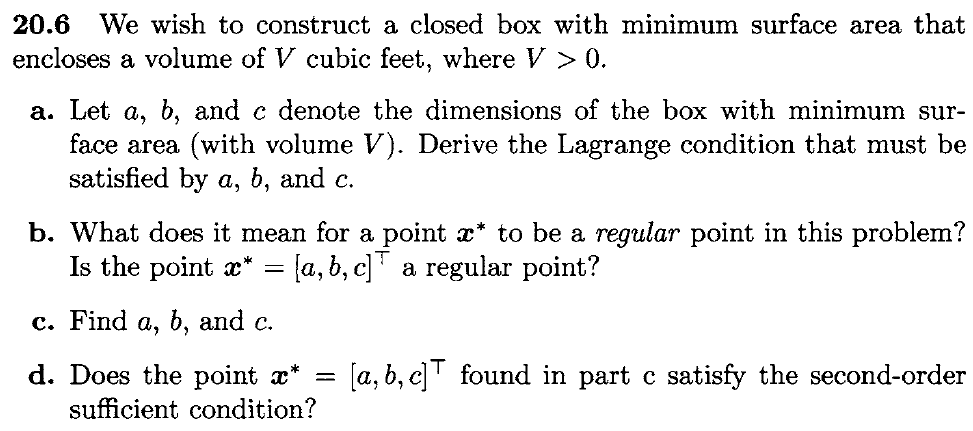

This problem corresponds to the optimization problem:

**minimize**: $2\left(x_1 x_2 +x_1 x_3 +x_2 x_3 \right)$

**subject** **to**: $x_1 x_2 x_3 =V$

## a)

Letting $x_1, x_2, x_3$ be the dimensions of the closed box, then the total surface area of the closed box is given by the function:


$$f(x)=2(x_1x_2+x_1x_3+x_2x_3)$$


f = @(x1, x2, x3) 2*(x1*x2 + x1*x3 + x2*x3);

This is the function to **minimize**.

The constraint is given by the function:


$$h\left(x\right)=x_1 x_2 x_3 -V$$


h = @(x1, x2, x3, V) x1*x2*x3-V;

Forming the Lagrangian:


$$L\left(x,\lambda \right)=f\left(x\right)+\lambda^T h\left(x\right)=2\left(x_1 x_2 +x_1 x_3 +x_2 x_3 \right)+\lambda \left(x_1 x_2 x_3 -V\right)$$


syms x1 x2 x3 V lambda
l = f(x1,x2,x3)+lambda*h

$$l = 2\,x_{1}\,x_{2}-\lambda \,\left(V-x_{1}\,x_{2}\,x_{3}\right)+2\,x_{1}\,x_{3}+2\,x_{2}\,x_{3}$$

Letting $x=\left\lbrack \begin{array}{c}
a\\
b\\
c
\end{array}\right\rbrack$, the Lagrangian conditions are then given by $\mathit{DL}\left(x,\lambda \right)$:


$$D_{x_1 } L\left(x,\lambda \right)=2\left(x_2 +x_3 \right)+\lambda x_2 x_3 =0\longrightarrow 2\left(b+c\right)+\lambda \mathit{bc}$$



$$D_{x_2 } L\left(x,\lambda \right)=2\left(x_1 +x_3 \right)+\lambda x_1 x_3 =0\longrightarrow 2\left(a+c\right)+\lambda a\text{c}$$



$$D_{x_3 } L\left(x,\lambda \right)=2\left(x_1 +x_2 \right)+\lambda x_1 x_2 =0\longrightarrow 2\left(a+b\right)+\lambda \mathit{ab}$$



$$D_{\lambda } L\left(x,\lambda \right)=x_1 x_2 x_3 -V=0\longrightarrow \mathrm{abc}-V=0$$


l1 = diff(l,x1)

$$l1 = 2\,x_{2}+2\,x_{3}+\lambda \,x_{2}\,x_{3}$$

l2 = diff(l,x2)

$$l2 = 2\,x_{1}+2\,x_{3}+\lambda \,x_{1}\,x_{3}$$

l3 = diff(l,x3)

$$l3 = 2\,x_{1}+2\,x_{2}+\lambda \,x_{1}\,x_{2}$$

l4 = diff(l,lambda)

$$l4 = x_{1}\,x_{2}\,x_{3}-V$$

## b)

## c)

Critical points which satisfy the lagrangian condition are found by solving the langrangian conditions with regards to the variables:


$$D_{x_1 } L\left(x,\lambda \right)=2\left(b+c\right)+\lambda \text{bc}$$



$$D_{x_2 } L\left(x,\lambda \right)=2\left(a+c\right)+\lambda a\mathrm{c}$$



$$D_{x_3 } L\left(x,\lambda \right)2\left(a+b\right)+\lambda \text{ab}$$



$$D_{\lambda } L\left(x,\lambda \right)=\text{abc}-V=0$$


Forming the linear system and solving through matrix reduction:

[x1_sol, x2_sol, x3_sol, lambda_sol] = solve(l1==0,l2==0,l3==0,l4==0,x1,x2,x3,lambda)

$$x1\_sol = \left(\begin{array}{c} \frac{V\,{\left(-\frac{64}{V}\right)}^{2/3}\,{\left(-\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\right)}^{2}}{16}\\ \frac{V\,{\left(-\frac{64}{V}\right)}^{2/3}\,{\left(\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\right)}^{2}}{16}\\ \frac{V\,{\left(-\frac{64}{V}\right)}^{2/3}}{16} \end{array}\right)$$

$$x2\_sol = \left(\begin{array}{c} \frac{V\,{\left(-\frac{64}{V}\right)}^{2/3}\,{\left(-\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\right)}^{2}}{16}\\ \frac{V\,{\left(-\frac{64}{V}\right)}^{2/3}\,{\left(\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\right)}^{2}}{16}\\ \frac{V\,{\left(-\frac{64}{V}\right)}^{2/3}}{16} \end{array}\right)$$

$$x3\_sol = \left(\begin{array}{c} \frac{V\,{\left(-\frac{64}{V}\right)}^{2/3}\,{\left(-\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\right)}^{2}}{16}\\ \frac{V\,{\left(-\frac{64}{V}\right)}^{2/3}\,{\left(\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\right)}^{2}}{16}\\ \frac{V\,{\left(-\frac{64}{V}\right)}^{2/3}}{16} \end{array}\right)$$

$$lambda\_sol = \left(\begin{array}{c} {\left(-\frac{64}{V}\right)}^{1/3}\,\left(-\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\right)\\ -{\left(-\frac{64}{V}\right)}^{1/3}\,\left(\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\right)\\ {\left(-\frac{64}{V}\right)}^{1/3} \end{array}\right)$$

Is is apparent from the solutions that all three sides must be equal:

a = V^(1/3)

$$a = V^{1/3}$$

b = V^(1/3)

$$b = V^{1/3}$$

c = V^(1/3)

$$c = V^{1/3}$$

Substituting the expressions for a, b and c into one of the Lagrange conditions allows for a solution for $\lambda$:


$$\lambda =-\frac{2\left(b+c\right)}{\mathrm{bc}}=-\frac{2V^{\frac{1}{3}} +2V^{\frac{1}{3}} }{V^{\frac{2}{3}} }=-\frac{4V^{\frac{1}{3}} }{V^{\frac{2}{3}} }=-\frac{4}{V^{\frac{1}{3}} }$$


lambda = solve(2*(b+c)+lambda*b*c==0,lambda)

$$lambda = -\frac{4}{V^{1/3}}$$

## d)

Evaluating the solution in terms of the SOSC:


$$y^T L\left(x,\lambda \right)y>0$$


Where:


$$L=F\left(x\right)+\left\lbrack \lambda H\left(x\right)\right\rbrack =D^2 f\left(x+\right)+\left\lbrack \lambda D^2 h\left(x\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & -\lambda_c  & -\lambda_b \\
-\lambda_c  & 0 & -\lambda_a \\
-\lambda_b  & -\lambda_a  & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & -\frac{4x_3 }{V^{\frac{1}{3}} } & -\frac{4x_2 }{V^{\frac{1}{3}} }\\
-\frac{4x_3 }{V^{\frac{1}{3}} } & 0 & -\frac{4x_1 }{V^{\frac{1}{3}} }\\
-\frac{4x_2 }{V^{\frac{1}{3}} } & -\frac{4x_1 }{V^{\frac{1}{3}} } & 0
\end{array}\right\rbrack$$


D2f = [diff(f,x1,x1) diff(f,x1,x2) diff(f,x1,x3);
       diff(f,x2,x1) diff(f,x2,x2) diff(f,x2,x3);
       diff(f,x3,x1) diff(f,x3,x2) diff(f,x3,x3)]

$$D2f = \left(\begin{array}{ccc} 0 & 2 & 2\\ 2 & 0 & 2\\ 2 & 2 & 0 \end{array}\right)$$


lambda_D2h = [lambda'*diff(h,x1,x1) lambda'*diff(h,x1,x2) lambda'*diff(h,x1,x3);
              lambda'*diff(h,x2,x1) lambda'*diff(h,x2,x2) lambda'*diff(h,x2,x3);
              lambda'*diff(h,x3,x1) lambda'*diff(h,x3,x2) lambda'*diff(h,x3,x3)]

$$lambda\_D2h = \left(\begin{array}{ccc} 0 & -\frac{4\,x_{3}}{\bar{V^{1/3}}} & -\frac{4\,x_{2}}{\bar{V^{1/3}}}\\ -\frac{4\,x_{3}}{\bar{V^{1/3}}} & 0 & -\frac{4\,x_{1}}{\bar{V^{1/3}}}\\ -\frac{4\,x_{2}}{\bar{V^{1/3}}} & -\frac{4\,x_{1}}{\bar{V^{1/3}}} & 0 \end{array}\right)$$


L = D2f+lambda_D2h

$$L = \begin{array}{l} \left(\begin{array}{ccc} 0 & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & 0 & \sigma_{3}\\ \sigma_{2} & \sigma_{3} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2-\frac{4\,x_{3}}{\sigma_{4}}\\ \sigma_{2}=2-\frac{4\,x_{2}}{\sigma_{4}}\\ \sigma_{3}=2-\frac{4\,x_{1}}{\sigma_{4}}\\ \sigma_{4}=\bar{V^{1/3}} \end{array}$$

Assuming a volume of 1, the proposed solution becomes:

x_opt = [1;1;1];

The Hessian of the Lagrangian then becomes:


$$L=D^2 f\left(x+\right)+\left\lbrack \lambda D^2 h\left(x\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 2 & 2\\
2 & 0 & 2\\
2 & 2 & 0
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
0 & -\lambda_c  & -\lambda_b \\
-\lambda_c  & 0 & -\lambda_a \\
-\lambda_b  & -\lambda_a  & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 2-\lambda_c  & 2-\lambda_b \\
2-\lambda_c  & 0 & 2-\lambda_a \\
2-\lambda_b  & 2-\lambda_a  & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & -2 & -2\\
-2 & 0 & -2\\
-2 & -2 & 0
\end{array}\right\rbrack$$



L = [0 -2 -2;
    -2 0 -2;
    -2 -2 0]

$$ans = \begin{array}{l} \left(\begin{array}{ccc} 0 & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & 0 & \sigma_{3}\\ \sigma_{2} & \sigma_{3} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2-\frac{4\,x_{3}}{\sigma_{4}}\\ \sigma_{2}=2-\frac{4\,x_{2}}{\sigma_{4}}\\ \sigma_{3}=2-\frac{4\,x_{1}}{\sigma_{4}}\\ \sigma_{4}=\bar{V^{1/3}} \end{array}$$

L =      0    -2    -2
    -2     0    -2
    -2    -2     0


Determining the an expression for the tangent plane:


$$T\left(x\right)=\left\lbrace \mathrm{Dh}\left(x\right)\ast y=0\right\rbrace$$


Where


$$\mathit{Dh}\left(x\right)=\left\lbrack \begin{array}{ccc}
x_2 x_3  & x_1 x_3  & x_1 x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\mathrm{bc} & \mathrm{ac} & \mathrm{ab}
\end{array}\right\rbrack$$


Dh = [diff(h,x1) diff(h,x2) diff(h,x3)]

$$Dh = \left(\begin{array}{ccc} x_{2}\,x_{3} & x_{1}\,x_{3} & x_{1}\,x_{2} \end{array}\right)$$

Solving for the tangent plane:


$$T\left(x\right)=\left\lbrace y:\text{Dh}\left(x\right)y=0\right\rbrace =\left\lbrace y:\left\lbrack \begin{array}{ccc}
\mathrm{bc} & \mathrm{ac} & \mathrm{ab}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
y_3 
\end{array}\right\rbrack =0\right\rbrace =\left\lbrace \left\lbrack \begin{array}{ccc}
1 & 1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
y_3 
\end{array}\right\rbrack =0\right\rbrace =\left\lbrace y:y_1 +y_2 +y_3 =0\right\rbrace$$


Therefore


$$y_1 =-\left(y_2 +y_3 \right)$$



$$y_2 =-\left(y_1 +y_3 \right)$$



$$y_3 =-\left(y_1 +y_2 \right)$$


syms y1 y2 y3
[y1_] = solve(y1+y2+y3==0,y1)

$$y1\_ = -y_{2}-y_{3}$$

[y2_] = solve(y1+y2+y3==0,y2)

$$y2\_ = -y_{1}-y_{3}$$

[y3_] = solve(y1+y2+y3==0,y3)

$$y3\_ = -y_{1}-y_{2}$$

y_ = [y1_; y2_; y3_];

Letting $y=\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
y_3 
\end{array}\right\rbrack$, then:


$$y^T L\left(x,\lambda \right)y=-2\left(y_1 \left(y_2 +y_3 \right)+y_2 \left(y_1 +y_3 \right)+y_3 \left(y_1 +y_2 \right)\right)$$


Substituting the expressions for $y_1$, $y_2$ and $y_3$ into the expression and evaluating the SOSC::


$$y^T L\left(x,\lambda \right)y=2\left(y_1^2 +y_2^2 +y_3^2 \right)>0$$


y = @(y) y'*L*y;
SOSC = simplify(y([y1_; y2_; y3_]))

$$SOSC = -4\,{\left|y_{1}\right|}^{2}-4\,{\left|y_{2}\right|}^{2}-4\,{\left|y_{3}\right|}^{2}-6\,y_{1}\,\bar{y_{2}}-6\,y_{2}\,\bar{y_{1}}-6\,y_{1}\,\bar{y_{3}}-6\,y_{3}\,\bar{y_{1}}-6\,y_{2}\,\bar{y_{3}}-6\,y_{3}\,\bar{y_{2}}$$

This is positive definite, which satisfies the SOSC and $x^\ast $ is therefore a strict **local minimizer**